# Dibujo Estatico

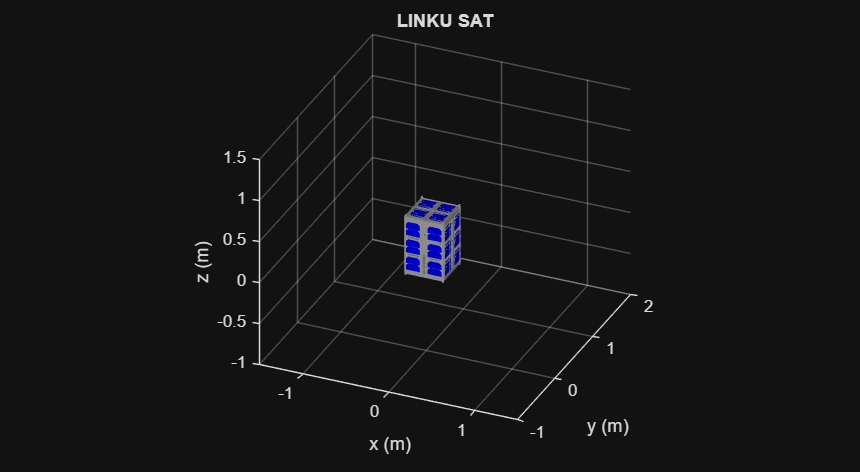

figure;
tam = get(0, 'ScreenSize');
set(gcf, 'position', tam);

axis equal;
%axis([xmin xmax ymin ymax zmin zmax]);
axis([-1.5  ,1.5  ,-1  ,2 ,-1  ,1.5]);  
grid on;
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
view([23.688 29.123]); 
camlight('headlight');
material('dull');
hold on; 

% dibujar el robot
dibujarLinku(0, 0, 0, 0, 0, 0, 2);

title('LINKU SAT');

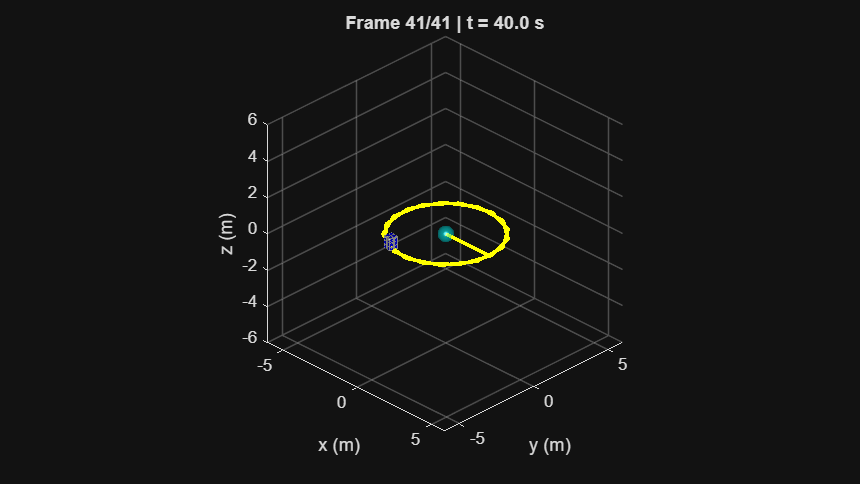

clc
clear
close all

ts = 1.0; % 1 segundo por paso
t = 0:ts:40; % 10 iteraciones TOTALES
radio = 3.0;

%% Calcular posiciones
for k = 1:length(t)
    ang = 0.6 * t(k);
    x(k+1) = radio * cos(ang);
    y(k+1) = radio * sin(ang);
    z(k+1) = 0;
    
    phi(k+1) = ang + pi/2;  % Solo vira siguiendo la órbita
    theta(k+1) = 0;
    psi(k+1) = 0;           % SIN GIRO (antes era 2*ang)
end

%% Escena
scene = figure;
tam = get(0, 'ScreenSize');
set(scene, 'position', [tam(1) tam(2) tam(3) tam(4)]);
axis equal;
axis([-6 6 -6 6 -6 6]);
grid on;
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
view([45, 30]);
camlight('headlight');
material('dull');
hold on;

%% Tierra
[X, Y, Z] = sphere(50);
surf(X*0.4, Y*0.4, Z*0.4, 'FaceColor', 'cyan', 'EdgeColor', 'none', 'FaceAlpha', 0.4);

%% Animación (10 frames)
for i = 1:length(t)
    delete(findall(gca, 'Type', 'patch'));
    dibujarLinku(x(i), y(i), z(i), phi(i), theta(i), psi(i), 2);
    plot3(x(1:i), y(1:i), z(1:i), 'y', 'LineWidth', 2);
    title(sprintf('Frame %d/%d | t = %.1f s', i, length(t), t(i)));
    pause(ts);
end